load data_HW02.mat

## Model Parameters


F = [0 1; 
    -1 0];

Ht = [1 0]; % h tilde 

function m = STM(t)
    m = [cos(t) sin(t);
          -sin(t) cos(t)];
end


## Least Squares

## Part A

% Regular 
regular_ls_estimate = LSEstimator(Z, T, F, Ht, @STM)

regular_ls_estimate =     1.0011
   -0.0055


## Part B

% Weighted 
weighted_ls_estimate = LSEstimator(Z, T, F, Ht, @STM, W)

weighted_ls_estimate =     1.0046
   -0.0077


## Part C

% With Previous info 
w_bar = diag([3,3]);
xk0 = [1;0];
informed_ls_estimate = LSEstimator(Z, T, F, Ht, @STM, W, xk0, w_bar)

informed_ls_estimate =     1.0044
   -0.0073


## Part D: LUMVE

H = [];

for idx = 1:length(T)
    stm = STM(T(idx)); 
    
    Hk = Ht * stm; 
    
    H = [H; Hk]; 
end

LPvv = diag(Pvv); 

x0_lumve = (H'*inv(LPvv)*H)\(H'*inv(LPvv)*Z)

x0_lumve =     1.0011
   -0.0055



Pxx = M*LPvv*M'

Pxx = 1.0e-03 *

    0.1884   -0.0067
   -0.0067    0.2091


## Part E: Sequential LUMVE

estimate_list = [];
P_list = [];

F = [0 1; 
    -1 0];

Ht = [1 0]; % h tilde 

% function m = STM(t)
%     m = [cos(t) sin(t);
%           -sin(t) cos(t)];
% end

x_p = [1;0];
Pxx_p = [.5^2, 0; 
         0     1^2];

Pvv = [.01];


for idx = 1:length(T)
    
    phi = STM(T(idx));
    xb_k = phi*x_p; % Prior 
    Pb_k = phi*Pxx_p*phi';

    Kk = Pb_k*Ht'*(Ht*Pb_k*Ht' + Pvv); 

    xh_k = x_p + Kk*(Z(idx) - Ht*xb_k); % Posterior
    Pxx_k = (eye(2) - Kk*Ht)*Pb_k; 


    x_p = xh_k;
    Pxx_p = Pxx_k;

    estimate_list = [estimate_list, x_p];

end




xh_k

xh_k =    -0.0105
   -0.2174


Pxx_k

Pxx_k =     0.0801    0.0057
    0.0057    0.0980


[Xhat_hist, P_hist, K_hist, innov_hist, S_hist] = lumve_sho(T, Z, .01, [1;0], diag([.5^2 1]), 1, 0);

Xhat_hist =     1.0155    0.9596    0.9437    0.9748    0.8857    0.8733    0.8664    0.7279    0.6734    0.6496    0.5368    0.4237    0.3331    0.3059    0.2148    0.1012    0.0117   -0.1060   -0.2109   -0.2858   -0.3604   -0.4597   -0.5606   -0.6442   -0.7338   -0.8070   -0.8588   -0.9198   -0.9554   -0.9820   -1.0083   -1.0188   -1.0248   -1.0105   -0.9780   -0.9539   -0.9079   -0.8569   -0.7924   -0.7253   -0.6515   -0.5818   -0.4980   -0.4065   -0.3067   -0.2107   -0.1117   -0.0093    0.0967    0.2024
         0   -0.3580   -0.3300   -0.1534   -0.4651   -0.4528   -0.4463   -0.6943   -0.7344   -0.7252   -0.8313   -0.9099   -0.9455   -0.9167   -0.9412   -0.9700   -0.9708   -0.9775   -0.9654   -0.9319   -0.8933   -0.8560   -0.8097   -0.7507   -0.6851   -0.6093   -0.5253   -0.4375   -0.3434   -0.2463   -0.1470   -0.0456    0.0563    0.1584    0.2588    0.3548    0.4487    0.5372    0.6210    0.6971    0.7661    0.8254    0.8791    0.9247    0.9619    0.9873    1.0033    1.0098    1.0

P_hist = P_hist(:,:,1) =

    0.0096         0
         0    1.0000


P_hist(:,:,2) =

    0.0066    0.0334
    0.0334    0.6619


P_hist(:,:,3) =

    0.0066    0.0329
    0.0329    0.3275


P_hist(:,:,4) =

    0.0062    0.0243
    0.0243    0.1621


P_hist(:,:,5) =

    0.0056    0.0174
    0.0174    0.0873


P_hist(:,:,6) =

    0.0050    0.0127
    0.0127    0.0511


P_hist(:,:,7) =

    0.0044    0.0095
    0.0095    0.0320


P_hist(:,:,8) =

    0.0040    0.0073
    0.0073    0.0211


P_hist(:,:,9) =

    0.0036    0.0057
    0.0057    0.0145


P_hist(:,:,10) =

    0.0033    0.0045
    0.0045    0.0103


P_hist(:,:,11) =

    0.0030    0.0036
    0.0036    0.0075


P_hist(:,:,12) =

    0.0027    0.0029
    0.0029    0.0056


P_hist(:,:,13) =

    0.0025    0.0023
    0.0023    0.0043


P_hist(:,:,14) =

    0.0023    0.0019
    0.0019    0.0033


P_hist(:,:,15) =

    0.0021    0.0016
    0.0016    0.0026


P_hist(:,:,16) =

    0.0020    0.0013
    0.0013    0.0021


P_hist(:

K_hist = K_hist(:,:,1) =

    0.9615
         0


K_hist(:,:,2) =

    0.6609
    3.3365


K_hist(:,:,3) =

    0.6641
    3.2851


K_hist(:,:,4) =

    0.6207
    2.4300


K_hist(:,:,5) =

    0.5573
    1.7398


K_hist(:,:,6) =

    0.4961
    1.2684


K_hist(:,:,7) =

    0.4426
    0.9485


K_hist(:,:,8) =

    0.3971
    0.7256


K_hist(:,:,9) =

    0.3583
    0.5656


K_hist(:,:,10) =

    0.3250
    0.4474


K_hist(:,:,11) =

    0.2962
    0.3580


K_hist(:,:,12) =

    0.2711
    0.2888


K_hist(:,:,13) =

    0.2489
    0.2344


K_hist(:,:,14) =

    0.2291
    0.1909


K_hist(:,:,15) =

    0.2114
    0.1557


K_hist(:,:,16) =

    0.1954
    0.1270


K_hist(:,:,17) =

    0.1809
    0.1034


K_hist(:,:,18) =

    0.1676
    0.0838


K_hist(:,:,19) =

    0.1554
    0.0675


K_hist(:,:,20) =

    0.1442
    0.0539


K_hist(:,:,21) =

    0.1339
    0.0425


K_hist(:,:,22) =

    0.1243
    0.0331


K_hist(:,:,23) =

    0.1154
    0.0253


K_hist(:,:,24) =

    0.1072
    0

innov_hist =     0.0161   -0.0769    0.0371    0.1108   -0.1237    0.0776    0.0964   -0.2257    0.0515    0.1628   -0.1253   -0.1011    0.0092    0.3007    0.0091   -0.0950    0.0435   -0.1239   -0.0504    0.1413    0.1272   -0.0961   -0.1533   -0.0519   -0.1793   -0.0921    0.0586   -0.1601    0.0463    0.0418   -0.1016   -0.0136   -0.1137    0.0646    0.2242   -0.1328    0.1212    0.0349    0.1466    0.0253    0.0117   -0.2286   -0.0337    0.0269    0.1272   -0.0360   -0.0155    0.0398    0.1188    0.1319


S_hist =     0.2600    0.0295    0.0298    0.0264    0.0226    0.0198    0.0179    0.0166    0.0156    0.0148    0.0142    0.0137    0.0133    0.0130    0.0127    0.0124    0.0122    0.0120    0.0118    0.0117    0.0115    0.0114    0.0113    0.0112    0.0111    0.0110    0.0109    0.0109    0.0108    0.0107    0.0107    0.0107    0.0106    0.0106    0.0105    0.0105    0.0105    0.0105    0.0105    0.0105    0.0105    0.0105    0.0105    0.0105    0.0105    0.0105    0.0105    0.0105    0.0105    0.0104


## Plotting

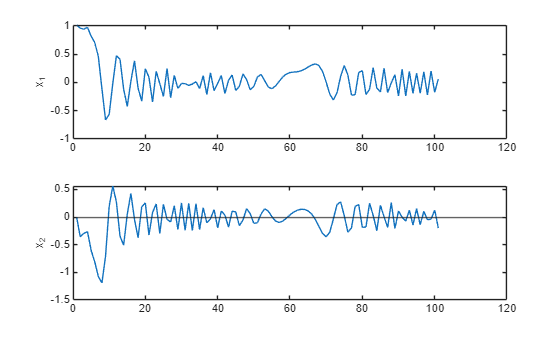

figure(Name="Estimate over observations")
tiledlayout(2,1)
nexttile 
plot(estimate_list(1,:))
yline(x0_lumve(1))
ylabel("x_{1}")
nexttile
plot(estimate_list(2,:))
ylabel("x_2")
yline(x0_lumve(2))